% Object Idea: Make a abstraction layer that scrubs for errorneous input and throws errors.
d2r = pi/180;
% Stephenson configuration and crank displacment
W1 = [-0.7432,0.4727];
V1 = [0.5825,0.1724];
U1 = [-0.1804,-0.4696];
G1 = [0.0197,1.1147];
L1 = [0.5671,1.2383];
L1_ = [1,0.25]; % _ is my token for *, e.g. L1_ = L1*
V1_ = [0.0552,-2.3906];
U1_ = [-0.2086,-0.2401];
G1_ = [0.086,-1.5542];
Fap2_ = [0,-900];
beta = -16*d2r; % crank displacment

% Solve for fourbar/dyad configuration, displacment angles (radians) shown for verification.
[alpha,gamma,alpha_,gamma_] = stephenson3Disp_InitConfig_Crank(W1,V1,U1,G1,L1,V1_,U1_,G1_,beta)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

alpha = -0.3662

gamma = 0.3703

alpha_ = -0.1602

gamma_ = 0.5779

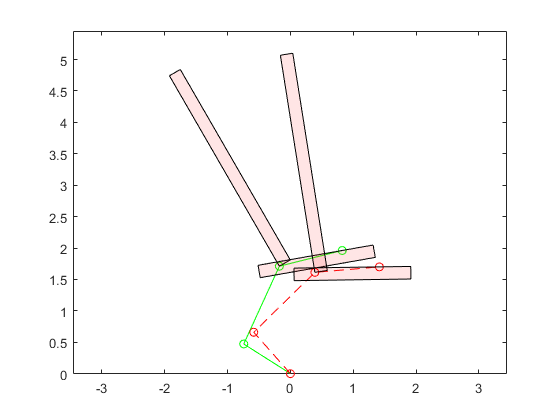


% Create 2nd Configuration, Vector = rotVec2D(originalVector,radians)
% Used later in symbolic subsitution
W2 = rotVec2D(W1,beta);
V2 = rotVec2D(V1,alpha);
U2 = rotVec2D(U1,gamma);
L2 = rotVec2D(L1,alpha);
V2_ = rotVec2D(V1_,alpha_);
U2_ = rotVec2D(U1_,gamma_);
L2_ = rotVec2D(L1_,alpha_);

% Configuraiton 1 Graphic
drawKinematicChain2D([W1;L1;L1_],[0,0],'-go');
hold on;

% Configuraiton 2 Graphic
drawKinematicChain2D([W2;L2;L2_],[0,0],'--ro');

% Seat Graphic (Relative Seat angles to the coupler/dyad was estimated)
X1 = [0 0 0.2 0.2];
Y1 = [3.5 0 0 3.5];
X2 = [-1.36 -1.36 0.5 0.5];
Y2 = [0 -.2, -.2 0];
drawPolygonToWorld2D([W1+L1],30*d2r,X1,Y1);
drawPolygonToWorld2D([W1+L1+L1_],10*d2r,X2,Y2);
drawPolygonToWorld2D([W2+L2],30*d2r+alpha,X1,Y1);
drawPolygonToWorld2D([W2+L2+L2_],10*d2r+alpha_,X2,Y2);


% Symbolicaly derive coeffecient matrix
    % Prep symbolic vectors
vectors = ["F_a2","F_a0","T_a0","W_2","F_p2","F_b2","L_2","V_2",...
    "F_c","U_2","F_ap2","F_b2_","V_2_","L_2_","F_c_","U_2_"];
symVec3D(vectors,true);
    % Formulate FBD equations
eq1 = F_a2 + F_a0 == 0;
eq2 = T_a0 + cross(W_2,F_a2) == 0;
eq3 = -F_a2 + F_p2 + F_b2 == 0;
eq4 = cross(L_2,F_p2) + cross(V_2,F_b2) == 0;
eq5 = -F_b2 + F_c == 0;
eq6 = cross(U_2,-F_b2) == 0;
eq7 = -F_p2 + F_ap2 + F_b2_ == 0;
eq8 = cross(V_2_,F_b2_) + cross(L_2_,F_ap2) == 0;
eq9 = F_c_ - F_b2_ == 0;
eq10 = cross(U_2_,-F_b2_) == 0;
sysOfEqs = [eq1, eq2, eq3, eq4, eq5, eq6, eq7, eq8, eq9, eq10];

    % Subsitute configuration parameters
eq = subsituteVec2DintoSym3DEQ(sysOfEqs,W2,W_2);
eq = subsituteVec2DintoSym3DEQ(eq,V2,V_2);
eq = subsituteVec2DintoSym3DEQ(eq,U2,U_2);
eq = subsituteVec2DintoSym3DEQ(eq,L2,L_2);
eq = subsituteVec2DintoSym3DEQ(eq,Fap2_,F_ap2); % Inconsisent naming convention for Fap2
eq = subsituteVec2DintoSym3DEQ(eq,V2_,V_2_);
eq = subsituteVec2DintoSym3DEQ(eq,U2_,U_2_);
eq = subsituteVec2DintoSym3DEQ(eq,L2_,L_2_);

% convert to Ax=b form
xvector = [T_a0,F_a0,F_a2,F_b2,F_c,F_p2,F_b2_,F_c_];
[A,b] = equationsToMatrix(eq,xvector);

% Solve vector x
A = double(A);
b = double(b);
x = A\b;

% Scrub for zeros
x = x.*(abs(x)>1); 

% Prep table
xvectorstr = arrayfun(@char, xvector, 'uniform', 0);
% construct table
table(xvectorstr',x)

ans = 24×2 table
      Var1           x     
    ________    ___________

    'T_a0_x'              0
    'T_a0_y'              0
    'T_a0_z'    -1.9109e+05
    'F_a0_x'     -2.062e+05
    'F_a0_y'     5.5986e+05
    'F_a0_z'              0
    'F_a2_x'      2.062e+05
    'F_a2_y'    -5.5986e+05
    'F_a2_z'              0
    'F_b2_x'           7125
    'F_b2_y'    -1.9988e+06
    'F_b2_z'              0
    'F_c_x'            7125
    'F_c_y'     -1.9988e+06
    'F_c_z'               0
    'F_p2_x'     1.9908e+05
